## Aula Teórica 14/11/2023 - Robótica

import RoboticaBiblioteca.*

printListaManipuladores()

--------------------> Lista de Manipuladores <-----------------------
1 - Manipulador Cartesiano: PPP
   1.1 - Manipulador Pórtico: cartesianos, mas com base em suportes
2 - Manipulador Cilíndrico: RPP
3 - Manipulador Articulados/Antropomórficos: RRR
4 - Manipulador Esféricos/Polares: RRP
5 - Manipulador SCARA: RRP, diferente do esférico, tem três eixos z0,
                       z1 e z2 todos verticais e paralelos


% l1 = l2 = 2 u.m.
% theta1 = 30
% theta2 = 50
% dTheta1 = 5°/s
% dTheta2 = 2°/s

dJ = [-2*sind(30)-2*sind(30+50), -2*sind(30+50);
      2*cosd(30)+2*cosd(30+50), 2*cosd(30+50)]

dJ =    -2.9696   -1.9696
    2.0793    0.3473


dTheta = [5; 2]

dTheta =      5
     2


Jacobiano = dJ*dTheta % °/s

Jacobiano =   -18.7873
   11.0913


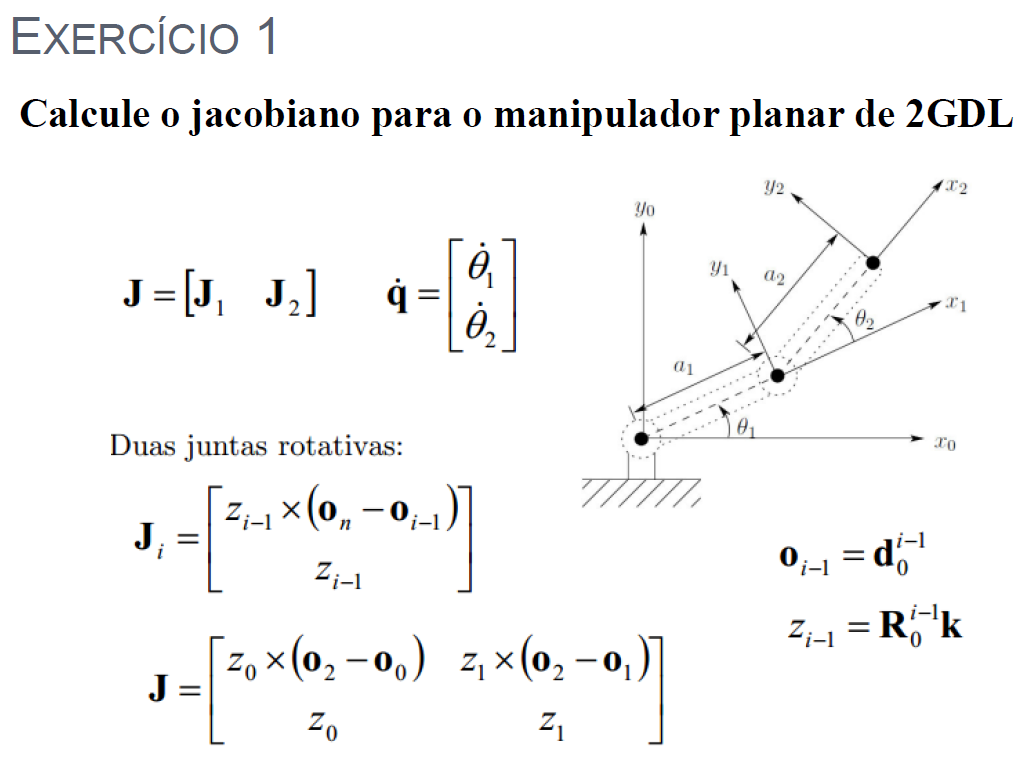

|  link  |   a   | alpha |    d    |    theta   |

| 0 - 1 |  a1  |     0    |    0    |  theta1*  |  R

| 1 - 2 |  a2  |     0    |    0    |  theta2*  |  R

syms a1 a2 theta1 theta2;
DH = [a1 0 0 theta1;
      a2 0 0 theta2];
[H02, Alc] = MatProgDenavit(DH)

A01 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & a_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & a_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A12 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & a_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & a_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$H02 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & a_{1}\,\cos\left(\theta_{1}\right)+a_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-a_{2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & a_{1}\,\sin\left(\theta_{1}\right)+a_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+a_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{2}=\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ \sigma_{3}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

Alc = 1×2 cell array
    {4×4 sym}    {4×4 sym}


H02 = simplify(H02)

$$H02 = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right) & -\sin\left(\theta_{1}+\theta_{2}\right) & 0 & a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Z0 = R00*K      R00 -> I

Z0 = K

Z0 = [0; 0; 1];
o2 = H02(1:3,4)

$$o2 = \left(\begin{array}{c} a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right)\\ a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\sin\left(\theta_{1}\right)\\ 0 \end{array}\right)$$

o0 = d00

o0 = [0; 0; 0]

o0 =      0
     0
     0


Z1 = R01*K

A01 = Alc{1};
Z1 = A01(1:3,1:3)*[0; 0; 1]

$$Z1 = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

o1 = d01

o1 = A01(1:3,4)

$$o1 = \left(\begin{array}{c} a_{1}\,\cos\left(\theta_{1}\right)\\ a_{1}\,\sin\left(\theta_{1}\right)\\ 0 \end{array}\right)$$

Jacobiano = [cross(Z0,(o2-o0)), cross(Z1, (o2-o1));
             Z0, Z1]

$$Jacobiano = \left(\begin{array}{cc} -a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-a_{1}\,\sin\left(\theta_{1}\right) & -a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\\ a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right) & a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 1 & 1 \end{array}\right)$$

a1 = 2;
a2 = 2;
theta1 = 30;
theta2 = 50;
DH = [a1 0 0 theta1;
      a2 0 0 theta2];
[H02, Alc] = MatProgDenavit(DH);

A01 = 
    0.8660   -0.5000         0    1.7321
    0.5000    0.8660         0    1.0000
         0         0    1.0000         0
         0         0         0    1.0000

A12 = 
    0.6428   -0.7660         0    1.2856
    0.7660    0.6428         0    1.5321
         0         0    1.0000         0
         0         0         0    1.0000



Z0 = [0; 0; 1]

Z0 =      0
     0
     1


o2 = H02(1:3,4)

o2 =     2.0793
    2.9696
         0


o0 = [0; 0; 0]

o0 =      0
     0
     0


A01 = Alc{1}

A01 =     0.8660   -0.5000         0    1.7321
    0.5000    0.8660         0    1.0000
         0         0    1.0000         0
         0         0         0    1.0000


Z1 = A01(1:3,1:3)*[0; 0; 1]

Z1 =      0
     0
     1


o1 = A01(1:3,4)

o1 =     1.7321
    1.0000
         0


Jacobiano = [cross(Z0,(o2-o0)), cross(Z1, (o2-o1));
             Z0, Z1]

Jacobiano =    -2.9696   -1.9696
    2.0793    0.3473
         0         0
         0         0
         0         0
    1.0000    1.0000


[J] = jacobiano(Alc, 'RR', true)

Z0 = 
     0
     0
     1

O0 = 
     0
     0
     0

Z1 = 
     0
     0
     1

O1 = 
    1.7321
    1.0000
         0

O2 = 
    2.0793
    2.9696
         0



J =    -2.9696   -1.9696
    2.0793    0.3473
         0         0
         0         0
         0         0
    1.0000    1.0000


Velocidade = J*[5; 2]

Velocidade =   -18.7873
   11.0913
         0
         0
         0
    7.0000


syms a1 a2 theta1 theta2;
DH = [a1 0 0 theta1;
      a2 0 0 theta2];
[H02, Alc] = MatProgDenavit(DH);

A01 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & a_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & a_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A12 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & a_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & a_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

[J] = jacobiano(Alc, 'RR', false);
simplify(J)

$$ans = \left(\begin{array}{cc} -a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-a_{1}\,\sin\left(\theta_{1}\right) & -a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\\ a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right) & a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 1 & 1 \end{array}\right)$$

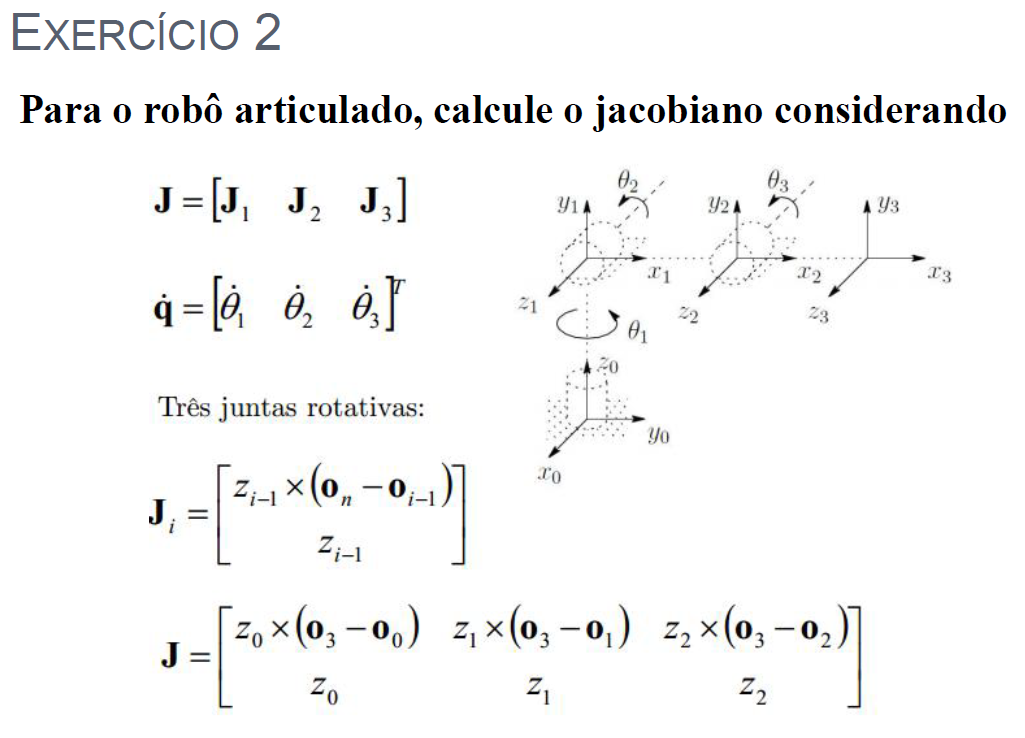

|  link  |   a   | alpha |    d    |         theta      |

| 0 - 1 |   0   |   90    |  d1    |  theta1* + 90  |  R

| 1 - 2 |  a2  |     0    |    0    |        theta2*    |  R

| 2 - 3 |  a3  |     0    |    0    |        theta3*    |  R

$\overset{\ldotp }{q} =\left\lbrack \begin{array}{c}
4\\
3\\
1
\end{array}\right\rbrack$°/s

d1 = 2;
a2 = 2;
a3 = 2;
theta1 = 90;
theta2 = 30;
theta3 = -60;
DH = [0 90 d1 (theta1 + 90);
      a2 0 0 theta2;
      a3 0 0 theta3];
[H03, Alc] = MatProgDenavit(DH)

A01 = 
    -1     0     0     0
     0     0     1     0
     0     1     0     2
     0     0     0     1

A12 = 
    0.8660   -0.5000         0    1.7321
    0.5000    0.8660         0    1.0000
         0         0    1.0000         0
         0         0         0    1.0000

A23 = 
    0.5000    0.8660         0    1.0000
   -0.8660    0.5000         0   -1.7321
         0         0    1.0000         0
         0         0         0    1.0000



H03 =    -0.8660   -0.5000         0   -3.4641
         0         0    1.0000         0
   -0.5000    0.8660         0    2.0000
         0         0         0    1.0000


Alc = 1×3 cell array
    {4×4 double}    {4×4 double}    {4×4 double}


A01 = Alc{1}

A01 =     -1     0     0     0
     0     0     1     0
     0     1     0     2
     0     0     0     1


A02 = Alc{1}*Alc{2}

A02 =    -0.8660    0.5000         0   -1.7321
         0         0    1.0000         0
    0.5000    0.8660         0    3.0000
         0         0         0    1.0000


A03 = Alc{1}*Alc{2}*Alc{3}

A03 =    -0.8660   -0.5000         0   -3.4641
         0         0    1.0000         0
   -0.5000    0.8660         0    2.0000
         0         0         0    1.0000


% Z0 = R00*K
K = [0; 0; 1];
Z0 = K

Z0 =      0
     0
     1


% Z1 = R01*K
Z1 = A01(1:3,1:3)*K

Z1 =      0
     1
     0



% Z2 = R01*K
Z2 = A02(1:3,1:3)*K

Z2 =      0
     1
     0


% o0 = d00
o0 = [0; 0; 0];
o1 = A01(1:3,4)

o1 =      0
     0
     2


o2 = A02(1:3,4)

o2 =    -1.7321
         0
    3.0000


o3 = A03(1:3,4)

o3 =    -3.4641
         0
    2.0000


J = [cross(Z0,(o3 - o0)), cross(Z1,(o3 - o1)), cross(Z2,(o3-o2));
     Z0, Z1, Z2]

J =          0         0   -1.0000
   -3.4641         0         0
         0    3.4641    1.7321
         0         0         0
         0    1.0000    1.0000
    1.0000         0         0


q = [4; 3; 1];
Jacobiano = J*q

Jacobiano =    -1.0000
  -13.8564
   12.1244
         0
    4.0000
    4.0000



$$\left\lbrack \begin{array}{c}
-1\\
-13\ldotp 85\\
12\ldotp 12\\
0\\
4\\
4
\end{array}\right\rbrack$$


As 3 primeiras são as velocidades lineares (vx, vy, vz) e as 3 últimas são as velocidades angulares (wx, wy, wz)

[J] = jacobiano(Alc,'RRR', true)

Z0 = 
     0
     0
     1

O0 = 
     0
     0
     0

Z1 = 
     0
     1
     0

O1 = 
     0
     0
     2

Z2 = 
     0
     1
     0

O2 = 
   -1.7321
         0
    3.0000

O3 = 
   -3.4641
         0
    2.0000



J =          0         0   -1.0000
   -3.4641         0         0
         0    3.4641    1.7321
         0         0         0
         0    1.0000    1.0000
    1.0000         0         0


Velocidade = J*q

Velocidade =    -1.0000
  -13.8564
   12.1244
         0
    4.0000
    4.0000
